# 5G NR Downlink Simulation with Beamforming

Beamforming is an essential component of the millimeter wave (mmWave) communication systems. This lab will demonstrate simple beamforming and channel modeling for a downlink transmissions in the 5G New Radio standard. In performing this lab, you will learn to:

- Model realistic antenna arrays and elements

- Compute beamforming vectors and the associated antenna factors

- Model multi-path fading channels in time-domain

- Modulate and demodulate symbols on the 5G NR downlink data channel using the  [MATLAB 5G Toolbox](https://www.mathworks.com/help/5g/index.html).

- Measure the quality of the demodulated symbols

- Organize complex projects into packages

% **Submission**: Complete all the sections marked `TODO`, and run the cells to make sure your scipt is working. When you are satisfied with the results,  [publish your code](https://www.mathworks.com/help/matlab/matlab_prog/publishing-matlab-code.html) to generate an html file. Print the html file to PDF and submit the PDF.

## Packages

Similar to python, you can group code with a common functionality into a [MATLAB package](https://www.mathworks.com/help/matlab/matlab_oop/scoping-classes-with-packages.html). Using packages enables better organized, more modular code. For several of the remaining labs, the repository contains a folder `+nr` containing some routines for simulating 5G NR systems. These functions were mostly helper functions taken from  [MATLAB's excellent demo](https://www.mathworks.com/help/5g/examples/nr-pdsch-throughput.html) on 5G throughput. In this lab, we will use just a small portion of the code.

To use the package, you must first add the folder containing this +nr to your MATLAB path. 

% TODO:  Use the MATLAB addpath() command to add the folder with the nr
% Sai Meghana Kuchana and Jitendra Project
% package.  You can use indirect referencing like '..'.

## Parameters

We will use the following parameters

fc = 28e9;          % carrier frequency in Hz
nantUE = [4,4];     % array size at the UE (mobile device)
nantgNB = [8,8];    % array size at the gNB (base station)
snrPerAntenna = 5; % target SNR per sample per antenna  
ueVel = [5 0 0];    % UE velocity vector in m/s
subcarrierSpacing = 120;  % sub-carrier spacing in kHz

% Creates simulation parameters for this lab
simParam = PDSCHSimParam('fc', fc);
NLayers = 1;    % number of layers
Modulation = 'QPSK';  
NRB = 51;  % number of resource blocks
SubcarrierSpacing = 120;  % SCS in kHZ
        

## Loading the 3GPP NR channel model

We will load the same channel as in the previous lab. 

dlySpread = 50e-9;  % delay spread in seconds
chan = nrCDLChannel('DelayProfile','CDL-A',...
    'DelaySpread',dlySpread, 'CarrierFrequency', fc, ...
    'NormalizePathGains', true);
chaninfo = info(chan);

% Get the gains and other path parameters
gain = chaninfo.AveragePathGains;
aoaAz  = chaninfo.AnglesAoA;
aoaEl = 90-chaninfo.AnglesZoA;
aodAz  = chaninfo.AnglesAoD;
aodEl = 90-chaninfo.AnglesZoD;
dly = chaninfo.PathDelays;

## Create the element

We will use the same patch element on the UE and gNB as before.

% Constants
vp = physconst('lightspeed');  % speed of light
lambda = vp/fc;   % wavelength

% Create a patch element
len = 0.49*lambda;
groundPlaneLen = lambda;
elem = patchMicrostrip(...
    'Length', len, 'Width', 1.5*len, ...
    'GroundPlaneLength', groundPlaneLen, ...
    'GroundPlaneWidth', groundPlaneLen, ...
    'Height', 0.01*lambda, ...
    'FeedOffset', [0.25*len 0]);

% Tilt the element so that the maximum energy is in the x-axis
elem.Tilt = 90;
elem.TiltAxis = [0 1 0];

## Creating an element wrapper class

A problem with the Phased Array Toolbox is that the element patterns are not smoothly interpolated. Also, we want to support antennas that have analytic functions for their pattern. To support this, we will use a wrapper class, InterpPatternAntenna. This class derives from the system.Matlab super-class. Its step method provides the directivity as a function of the angles. We can then replace this class with any other class that provides a formula for the directivity.

% Creating wrapper object for the elem
elemInterp = InterpPatternAntenna(elem,fc);

## Create the arrays

We next create arrays at the UE and gNB

% Creating two URAs with the sizes nantUE and nantgNB. Both arrays should be separated at 0.5 lambda.
dsep = 0.5*lambda;
arrgNB0 = phased.URA(nantgNB,dsep); % URA for the gNB
arrUE0 = phased.URA(nantUE,dsep); % URA for the UE

## Create the array with axes

Similar to the previous lab, we will create a wrapper class around the arrays to handle orientation modeling. The ArrayWithAxes class includes an array along with axes to store the orientation of the array relative to some global coordinate system.

% Create ArrayWithAxes objects for the gNB and UE with the 
% arrays, arrUE0 and arrgNB0, and elements, elemInterp.
velgNB = [30,0,0];
velUE = [30,0,0];
arrgNB = ArrayWithAxes('elem', elemInterp, 'arr', arrgNB0, 'vel', velgNB, 'fc', fc);
arrUE  = ArrayWithAxes('elem', elemInterp, 'arr', arrUE0, 'vel', velUE, 'fc', fc);

## Rotate the UE and gNB antennas

Similar to the previous lab, we will rotate the arrays to the path with the maximum gain.

% Index of the path with the maximum gain
[~,im] = max(gain);

% arrUE.alignAxes() and arrgNB.alignAxes() to align to the corresponding angles of arrival and departure.
arrUE.alignAxes(aoaAz(im),aoaEl(im));
arrgNB.alignAxes(aodAz(im),aodEl(im));

## Compute the gains along the paths

To see the potential gain from beamforming, we will compute the array factor and element gain along each path

% Calculating spatial signatures and element gains of each path
% based on their angles of arrival and departure.

[utx, elemGainTx] = arrgNB.step(aoaAz, aoaEl);
[urx, elemGainRx] = arrUE.step(aodAz, aodEl);

% TODO:  Compute the TX beamforming direction at the gNB and RX BF 
% direction at the UE.  To keep the beamforming simple, we will align
% the directions to the strongest path.  Thus, the BF directions should
% be complex conjugate of the steering vectors.  They should also be
% normalized.
%     wtx = TX direction at the gNB
%     wrx = RX direction at the UE

wtx = conj(utx(:,im));
wtx = wtx / norm(wtx);

wrx = conj(urx(:,im));
wrx = wrx / norm(wrx);

% Computing the array factors at the gNB and UE
% from the BF vectors and spatial signatures, utx and urx.
AFgNB = 10*log10( abs(sum(wtx.*utx, 1)).^2 ); % AFgNB(i) = array factor gain on path i in dBi at the gNB
AFUE = 10*log10( abs(sum(wrx.*urx, 1)).^2 ); % AFUE(i) = array factor gain in path i dBi at the UE
gainDir = gain + AFgNB + AFUE;
stem(dly/1e-9,[gain;gainDir]','BaseValue', -40);
grid on;
xlabel('Delay(ns)')
ylabel('Gain(dB)')
legend('Omni', 'with directivity')

## Generate a 5G TX signal

We will now test the array processing by transmitting a 5G downlink signal. Specifically, we will transmit random QPSK symbols on the locations of the PDSCH channel, the channel in the 5G NR standard for data. The lab supplies a simple class, NRgNBTx, to perform this function. Most of the class is implemented and extensively uses commands from the 5G Toolbox.


% Creating a TX object using the NRgNBTx object with the simParam
% object.

tx = NRgNBTx(simParam);
% Set the BF vector of the TX
tx.txBF = wtx;

% Generating one slot of symbols using the step() method
x = tx.step();
%imagesc(abs(x));
%colorbar()

The slot of data produced by this data contains two channels: * PDSCH: The downlink data channel * DM-RS: Demodulation reference signals for channel estimation at the RX. We will discuss this later.


fprintf(1, 'Sampling rate = %7.2f MHz\n', tx.waveformConfig.SampleRate/1e6);
fprintf(1,'Slot duration = %7.2f us\n', size(x,1)*1e6/tx.waveformConfig.SampleRate);
nchan = 2;
fprintf(1,'Total REs: %d \n', numel(tx.ofdmGridLayer));
fprintf(1,'REs for DMRS: %d \n', length(tx.dmrsSym));
fprintf(1,'REs for PDSCH: %d \n', length(tx.pdschSym));

## Create the MIMO multi-path channel

We will now simulate the channel in time-domain. The lab supplies code, MIMOMPChan, which is a MIMO version of the SISOMPChan you created in the previous lab.

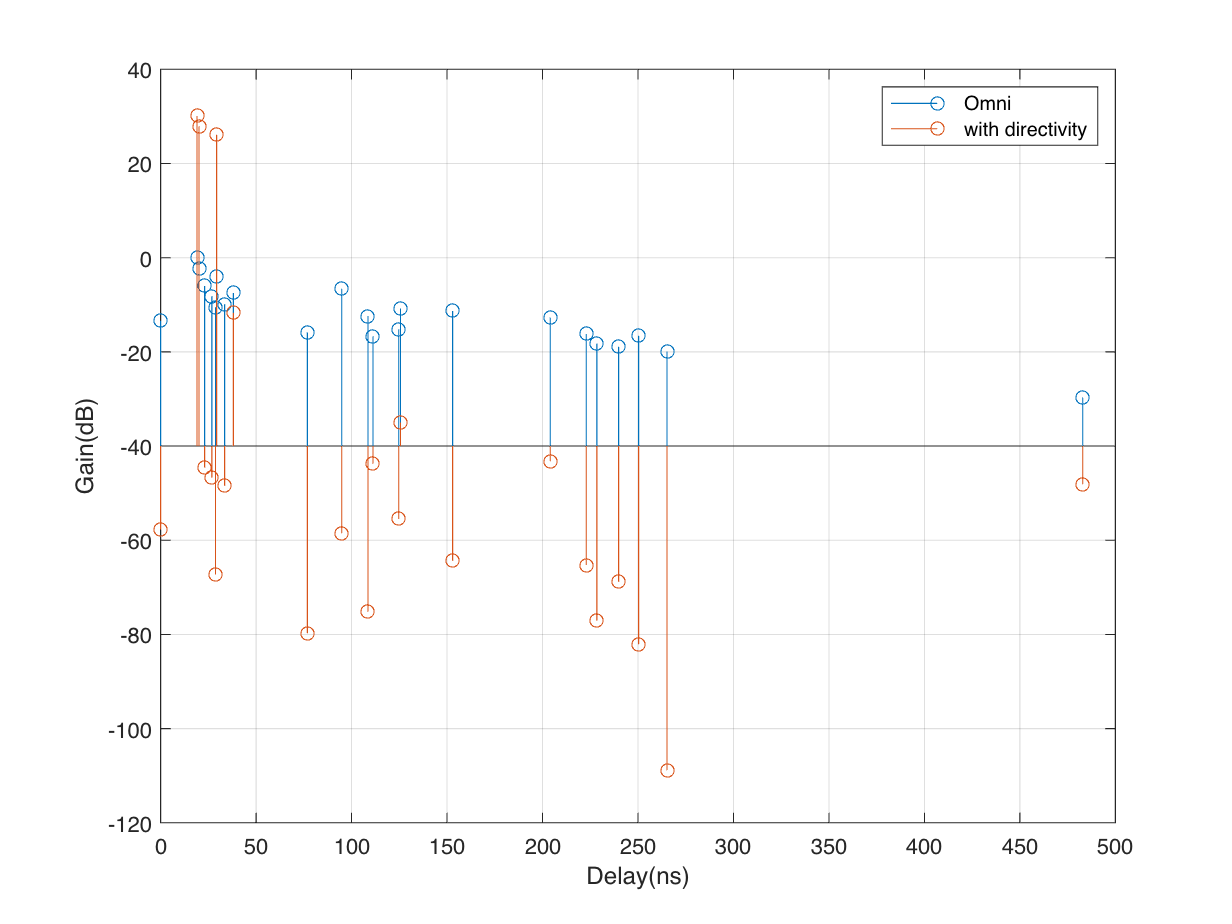

% Creating the MIMOMPChan object with all the AoAs, AoDs, gains

% arrays, delays and sampling rate.  
chan = MIMOMPChan('fsamp', tx.waveformConfig.SampleRate, 'dly', dly, 'gain', gainDir, ...
                 'txArr', arrgNB, 'rxArr', arrUE, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
                  'aodAz', aodAz, 'aodEl', aodEl);
% y: output of channel
y = chan.step(x);

## Add noise

In multi-antenna receivers, the SNR is typically quoted as the SNR per antenna. Specifically, suppose that ynoisy = y + w. The SNR per antenna is E|y(t,j)|^2/E|w(t,j)|^2. Create a matrix ynoisy using the snrPerAntenna.

snr = 20;
[n,m] = size(y);
wvar = mean(abs(y(:)).^2)*10^(-0.1*snr);
ynoisy = y + sqrt(wvar/2)*(randn(n,m) + 1i*randn(n,m));

## Create a UE receiver

We will now demodulate the noisy symbols. The lab supplies a simple class, NRUErx, to perform this function. Most of the class is implemented and extensively uses commands from the 5G Toolbox. You just have to do a small modification to support BF. 

% Creating a RX object with the correct rxBF vector
rx = NRUERx(simParam, 'rxBF', wrx);
rx.step(ynoisy);
% The equalized symbols are now stored in rx.pdschSym. 
plot(real(rx.pdschSymEq),imag(rx.pdschSymEq),'o')

## Measure the SNR

When you plot the final equalized symbols you will see that there is a lot of noise. Also there is a phase rotation which comes from the Doppler shift that was not corrected. In reality, you would have some carrier frequency offset to remove this. We will also discuss this later. For now, we measure the post-equalized SNR.

One way to measure the post-equalized SNR is: snrEq = 10*log10( E|r|^2 / E| r - h*x |^2 ) where r is the recived raw symbols (in this case rx.pdschSymRaw) h is the channel estimate (rx.pdschChanEst) and x is the transmitted symbols (tx.pdschSym).

% The post-equalized SNR in dB
Eerr = mean(abs(rx.pdschSymRaw - rx.pdschChanEst.*tx.pdschSym).^2);

Sampling rate =  122.88 MHz


Erx = mean(abs(rx.pdschSymRaw).^2);

Slot duration =  125.39 us


snrEq = 10*log10(Erx/Eerr);
fprintf(1,'SNR post equalization = %7.2f\n',snrEq);

Total REs: 8568 


Since the RX signal ynoisy already includes the antenna element gain, The post-equalized SNR should be: snrTheory = snrPerAntenna + bwGain + BFGain where BFGain is the BF gain and bwGain is the gain since we are transmitting on tx.waveformConfig.NSubcarriers out of tx.waveformConfig.Nfft FFT frequency bins. Ideally the BF gain is the number of UE antennas. You will notice that snrTheory is a little higher than what we received. This is mostly since the receiver we built here does not compensate for frequency offset.

% SnrTheory.

REs for DMRS: 306 


nscPerRB = 12;

REs for PDSCH: 7032 


nsc = simParam.carrierConfig.NSizeGrid * nscPerRB;
nantrx = prod(nantUE);
bwGain = 10*log10(tx.waveformConfig.Nfft/nsc);
snrTheory = snrPerAntenna + bwGain + 10*log10(nantrx);
fprintf(1,'SNR theoretical = %7.2f\n',snrTheory)

# **Loading the Data (Test on real Data)**

load roomPathData.mat

Select a RX Location

% Select an approximate RX position in the room
rxPos = [12,-6];   % A strong LOS point
% rxPos = [13,-12];  % A strong NLOS point
%rxPos = [15,-14];  % A weak NLOS point
%rxPos = [16,-15];  % A very weak NLOS point

% Find the index in the ray tracing data closest to the desired position
d = sum((pathData.rxPos - rxPos).^2, 2);
[dmin, indRx] = min(d);

### **Reading the Data**

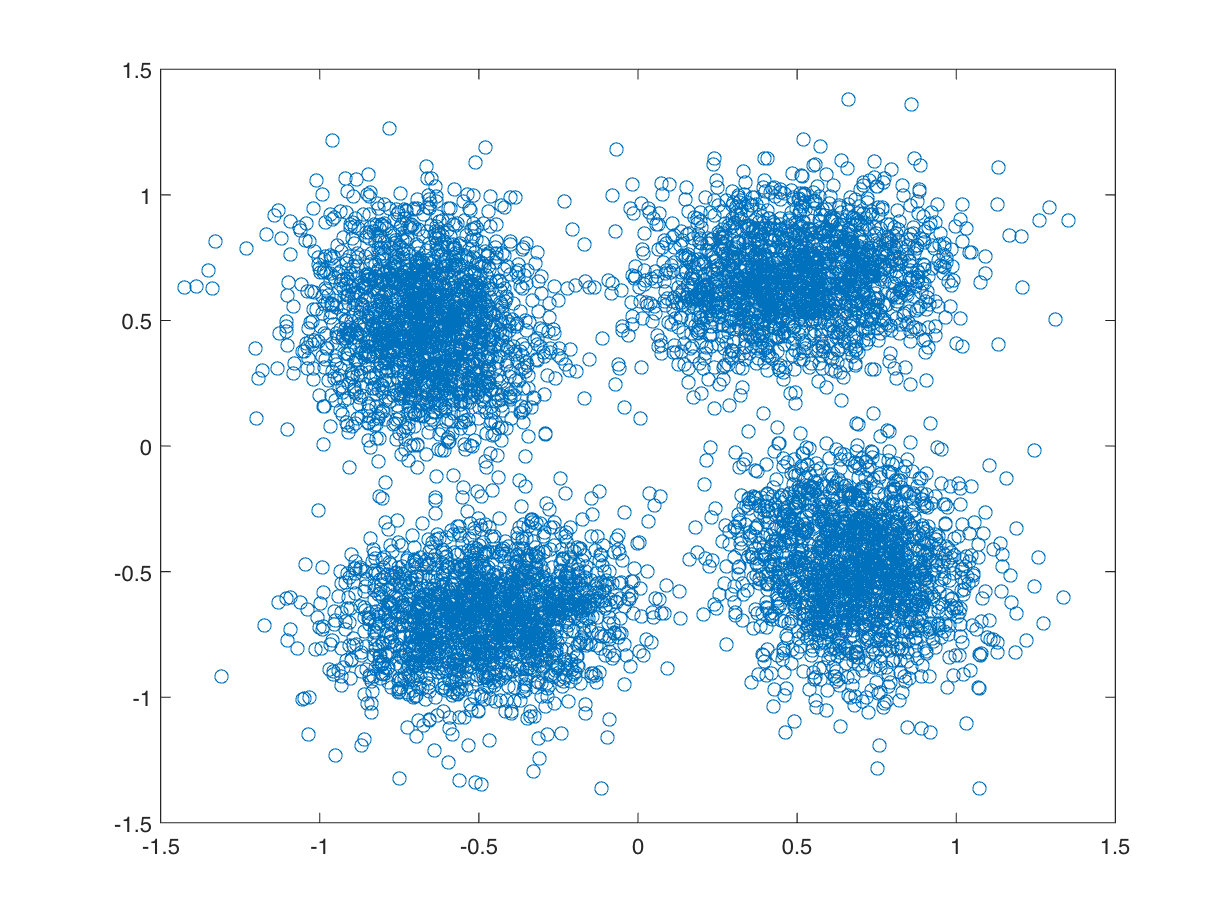

gain = pathData.gain(indRx,:);
aoaAz  = pathData.aoaAz(indRx,:);
aoaEl = 90-pathData.aoaEl(indRx,:);
aodAz  = pathData.aodAz(indRx,:);

aodEl = 90-pathData.aodEl(indRx,:);
dly = pathData.dly(indRx,:);

### **We now plot the TX and RX position**

clf;
noDataValue = 3;  % Use this value for positions with no data

% Legend labels

SNR post equalization =    7.53


legendLabels = {'Outage', 'LOS', 'NLOS', 'NoData'};

% Create a mapper for plotting
mapper = DataMapper(pathData.rxPos, pathData.posStep);

% Call the plot.  Use `plotHold=true` to hold the plot so we can overlay
% other items
mapper.plot(pathData.linkState, 'noDataValue', noDataValue, ...
    'LegendLabels', legendLabels, 'plotHold',true);

SNR theoretical =   19.28



% Overlay the TX position
txPos = pathData.txPos;
plot(txPos(1), txPos(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'TX');
plot(pathData.rxPos(indRx,1), pathData.rxPos(indRx,2), 'rx', ...
    'MarkerSize', 10, 'DisplayName', 'RX');
hold off;


% Display the legend
legend('Location', 'SouthEast');

## Creating the Antenna Elements

velgNB = [30,0,0];
velUE = [30,0,0];
arrgNB = ArrayWithAxes('elem', elemInterp, 'arr', arrgNB0, 'vel', velgNB, 'fc', fc);
arrUE  = ArrayWithAxes('elem', elemInterp, 'arr', arrUE0, 'vel', velUE, 'fc', fc);
[~,im] = max(gain);
arrUE.alignAxes(aoaAz(im),aoaEl(im));
arrgNB.alignAxes(aodAz(im),aodEl(im));
[utx, elemGainTx] = arrgNB.step(aoaAz, aoaEl);
[urx, elemGainRx] = arrUE.step(aodAz, aodEl);

wtx = conj(utx(:,im));
wtx = wtx / norm(wtx);
wrx = conj(urx(:,im));
wrx = wrx / norm(wrx);
AFgNB = 10*log10( abs(sum(wtx.*utx, 1)).^2 );
AFUE = 10*log10( abs(sum(wrx.*urx, 1)).^2 );

gainDir = gain + AFgNB + AFUE;
stem(dly/1e-9,[gain;gainDir]','BaseValue', -40);
grid on;
xlabel('Delay(ns')
ylabel('Gain(dB)')
legend('Omni', 'with directivity');
% generatin tx signal
tx = NRgNBTx(simParam);
tx.txBF = wtx;
x = tx.step();

chan = MIMOMPChan('fsamp', tx.waveformConfig.SampleRate, 'dly', dly, 'gain', gainDir, ...
                 'txArr', arrgNB, 'rxArr', arrUE, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
                  'aodAz', aodAz, 'aodEl', aodEl);
y = chan.step(x);
%snr = 20;
[n,m] = size(y);
wvar = mean(abs(y(:)).^2)*10^(-0.1*snrPerAntenna);
ynoisy = y + sqrt(wvar/2)*(randn(n,m) + 1i*randn(n,m));

rx = NRUERx(simParam, 'rxBF', wrx);
rx.step(ynoisy);
plot(real(rx.pdschSymEq),imag(rx.pdschSymEq),'o')

## Measure the SNR

Eerr = mean(abs(rx.pdschSymRaw - rx.pdschChanEst.*tx.pdschSym).^2);
Erx = mean(abs(rx.pdschSymRaw).^2);
snrEq = 10*log10(Erx/Eerr);
fprintf(1,'SNR post equalization = %7.2f\n',snrEq);
% TODO:  Compute and print snrTheory.
nscPerRB = 12;
nsc = simParam.carrierConfig.NSizeGrid * nscPerRB;
nantrx = prod(nantUE);
bwGain = 10*log10(tx.waveformConfig.Nfft/nsc);
snrTheory = snrPerAntenna + bwGain + 10*log10(nantrx);
fprintf(1,'SNR theoretical = %7.2f\n',snrTheory)

### **Till now we align beamforming vector to the max gain path now let's fix the TX antenna at some fixed angle and vary the rotate the RX, calculate the post equalization SNR to see the impact**

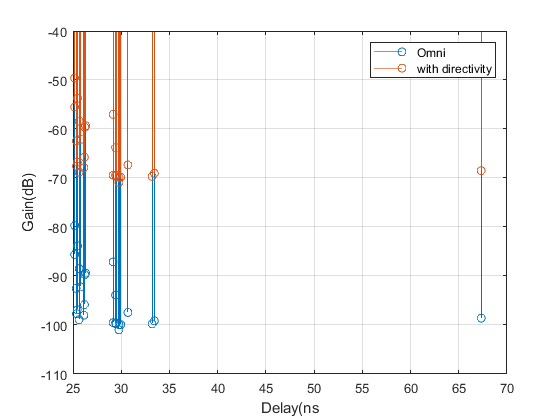

% different rotation angle to test
az = (-180:5:180); 
el = (-90:5:90);

naz = length(az);
nel = length(el);

npath = length(gain);

% Creating the array
arrgNB = ArrayWithAxes('elem', elemInterp, 'arr', arrgNB0, 'vel', velgNB, 'fc', fc);

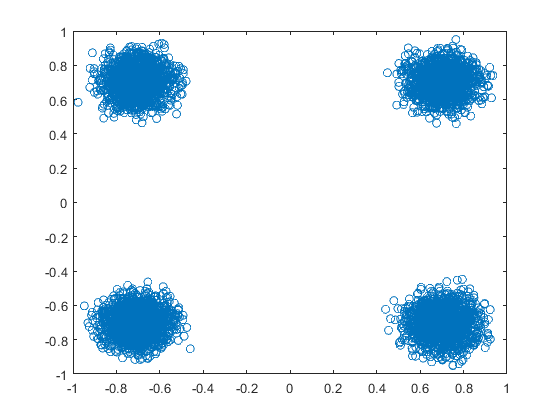

arrUE  = ArrayWithAxes('elem', elemInterp, 'arr', arrUE0, 'vel', velUE, 'fc', fc);

% Aligning the tx at some fixed location along the max gain path
arrgNB.alignAxes(aodAz(im),aodEl(im));


snr = zeros(naz, nel); % to hold the snr values

for i = 1:naz
    for j = 1:nel
        arrUE.alignAxes(az(i),el(j));
        [utx, elemGainTx] = arrgNB.step(aoaAz, aoaEl);
        [urx, elemGainRx] = arrUE.step(aodAz, aodEl);

        wtx = conj(utx(:,im));
        wtx = wtx / norm(wtx);

        wrx = conj(urx(:,im));
        wrx = wrx / norm(wrx);
        %AFgNB = 10*log10( abs(sum(wtx.*utx, 1)).^2 );
        %AFUE = 10*log10( abs(sum(wrx.*urx, 1)).^2 );

        %gainDir = gain + AFgNB + AFUE;

SNR post equalization =   19.61


        
        % generatin tx signal
        tx = NRgNBTx(simParam);
        tx.txBF = wtx;
        x = tx.step();

        chan = MIMOMPChan('fsamp', tx.waveformConfig.SampleRate, 'dly', dly, 'gain', gainDir, ...

SNR theoretical =   19.28


                     'txArr', arrgNB, 'rxArr', arrUE, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
                     'aodAz', aodAz, 'aodEl', aodEl);
        y = chan.step(x);

        [n,m] = size(y);
        wvar = mean(abs(y(:)).^2)*10^(-0.1*snrPerAntenna);
        ynoisy = y + sqrt(wvar/2)*(randn(n,m) + 1i*randn(n,m));
        
        
        rx = NRUERx(simParam, 'rxBF', wrx);
        rx.step(ynoisy);
        
        Eerr = mean(abs(rx.pdschSymRaw - rx.pdschChanEst.*tx.pdschSym).^2);
        Erx = mean(abs(rx.pdschSymRaw).^2);
        snrEq = 10*log10(Erx/Eerr);
        
        snr(i,j) = snrEq;
    end
end
    

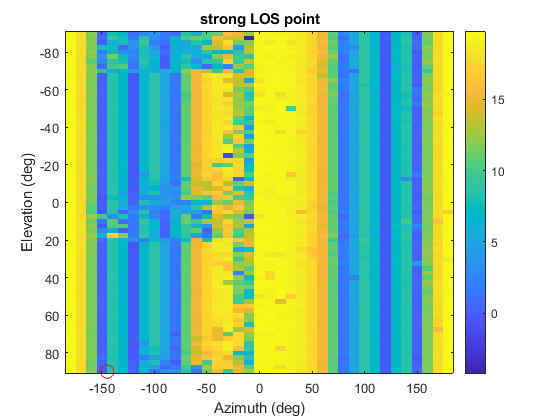

   
imagesc(az,el,snr);
colorbar();
hold on;
plot(aoaAz(im),aoaEl(im), 'ro', 'Markersize', 10);
hold off;
xlabel('Azimuth (deg)');
ylabel('Elevation (deg)');

 title(sprintf('strong LOS point'));
 